Reset

clear

Open DSD

% drivingScenarioDesigner("testingTrack/kidneyBeanTest.mat");

Initialize bKin & driving scenario

clear 

% Maximum speeds estimated from external source
% https://bikesreviewed.com/fun/bike-speed/
bISpeedRange = [0, 13.4];
bikeInstance = bicycleKinematics("VehicleSpeedRange",bISpeedRange);
bIInitial = [5.166 14.157 deg2rad(-50)];

scenario = kidneyBeanTest;
bicycle = actor(scenario,'ClassID',3,'Position',[5.166 14.157 0]','Length',1.5,'Width',0.45,'Yaw',-50);
bounds = roadBoundaries(scenario);
outerBounds = bounds{1};
outerBounds = [outerBounds(end:-1:1,1),outerBounds(end:-1:1,2)]

outerBounds =     7.2242   14.6029
    8.2538   12.3512
    8.6959    9.9965
    8.6641    7.6814
    8.2881    5.4791
    7.6922    3.4105
    6.9863    1.4638
    6.2647   -0.3892
    5.6096   -2.1789
    5.0946   -3.9277


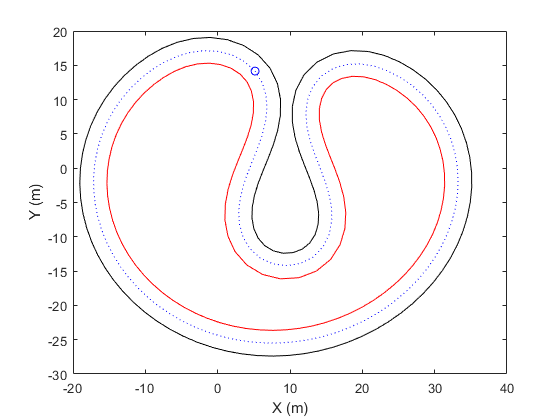

innerBounds = bounds{2};
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));
plot(outerBounds(:,1),outerBounds(:,2),'k')
hold on
plot(innerBounds(:,1),innerBounds(:,2),'r')
plot(centers(:,1),centers(:,2),':b')
plot(5.166,14.157,'ob')
xlabel("X (m)")
ylabel("Y (m)")
hold off

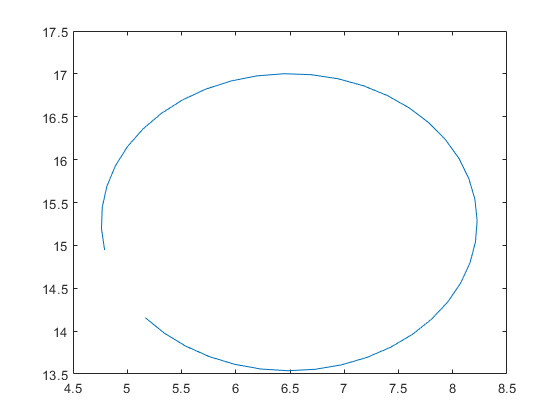

routeProperties = struct;

routeProperties.outer = outerBounds;
routeProperties.inner = innerBounds;
routeProperties.center = centers;

% I need a way to generate a list of waypoints and speeds accomodating for
% acceleration limitations. If we use 0.05 second steps, x = x0 + dT*vx

[t,y] = ode45(@(t,y)derivative(bikeInstance,y,[5,pi/6]),0:0.05:2,bIInitial);
plot(y(:,1),y(:,2))

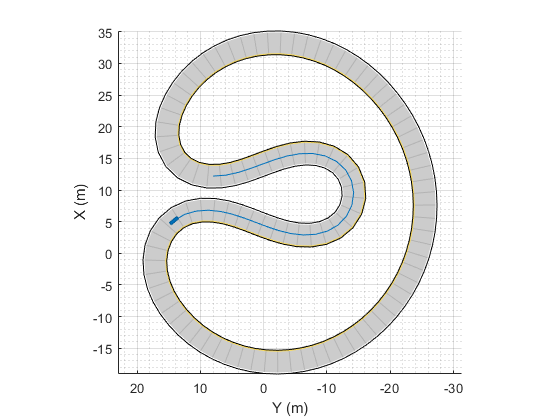

plot(scenario)
hold on
plot(centers(1:31,1),centers(1:31,2))
hold off

% while advance(scenario)
%     pause(scenario.SampleTime)
% end